# Finding the Area of Baker Lake: 1952 and today

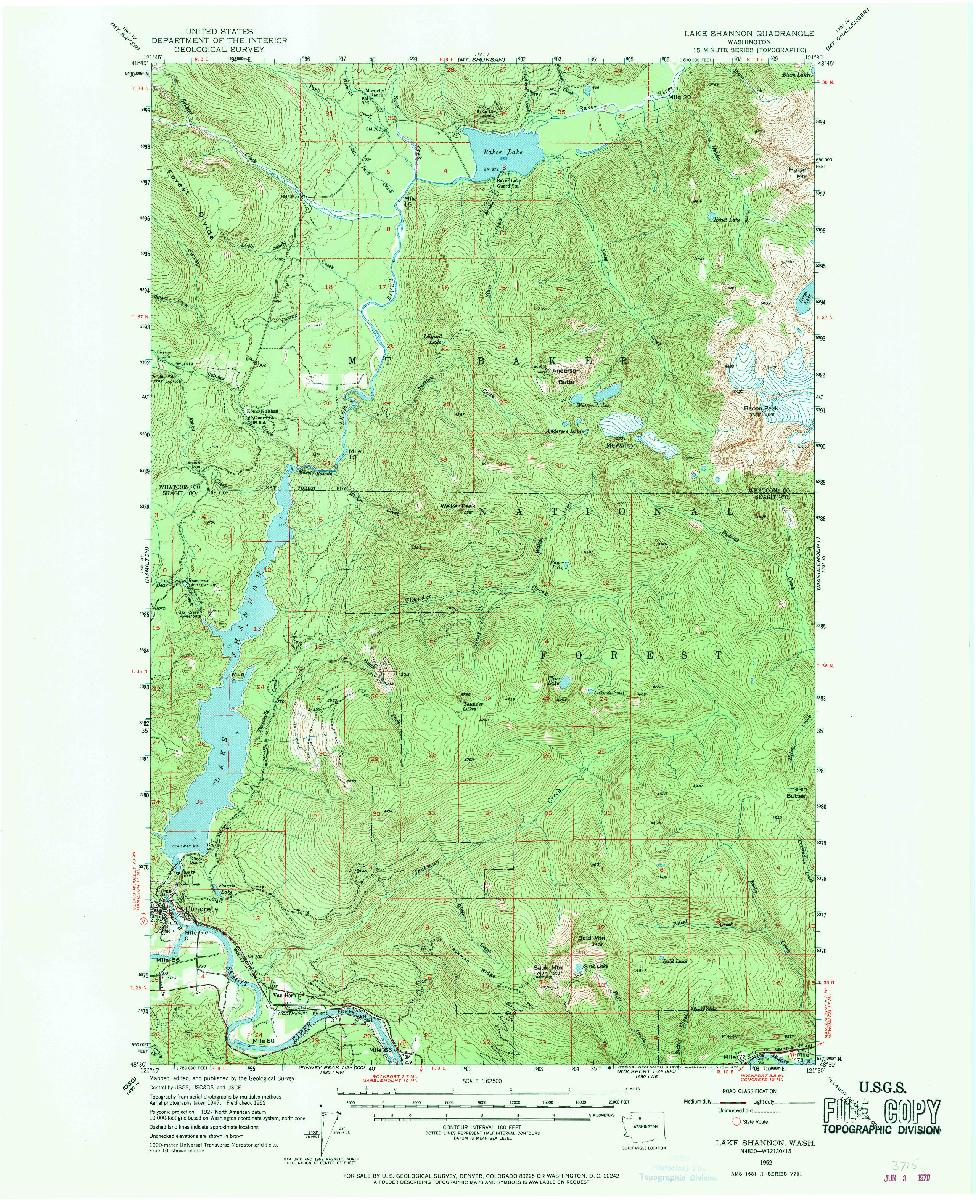

Lake Shannon topographic map, 1952 produced by the [U.S. Geological Survey](https://ngmdb.usgs.gov/topoview/viewer/#10/48.5857/-121.2904)

Baker Lake was significantly enlarged following the building of the Upper Baker Dam in 1959. There is a U.S. Geological Survey map from 1952 above that allows us to calculate the original surface area of the lake. Then repeat the analysis using a modern map of Baker Lake. Baker Lake is part of the Baker River Hydroelectric Project, including the Lower Baker Dam, built in 1925, and Lake Shannon, also visible on the map. The Baker River Hydroelectric Project is the most significant contributor of hydroelectric power for Puget Sound Energy which provides electricity to large parts of western Washington State, including the greater Seattle metro area.

**Before you get started:**

This live script is intended to be used with the code visible for interaction. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**.  Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Collect Data

First, collect data by identifying sufficient data points moving counterclockwise around the edge of the lake to define it well. Select either `"1952"` or `"modern-day"` and then run this section to collect data. Click to add points to your lake edge data set in order. When you are done collecting data, double-click or click on your initial point. 

choice = "1952";
if choice == "1952"
    lake = imread("WA_Lake Shannon_241902_1952_62500.jpg");
    imshow(lake)
    pause(1)
    disp("That map is hard to read! Let's zoom in on the section we want to analyze.")
    openfig("BakerLake.fig");
elseif choice == "modern-day"
    figure
    geoplot(48.7,-121.658)
    geolimits([48.63,48.75],[-121.665 -121.65])
    geobasemap('satellite')
end
roi = drawpolygon;
    x = roi.Position(:,1);
    y = roi.Position(:,2);

Plot the data you collected. How well does it match the lake?

if choice == "1952"
    f = openfig("BakerLake.fig");
    hold on
    plot(x,y,"LineWidth",3)
    hold off
elseif choice == "modern-day"
    figure;
    geoplot(x,y,"LineWidth",3)
    geobasemap('satellite')
    title("Baker Lake")
end

 **Reflect**.

- Does your data form a closed curve? If not, how can you modify your data to force the curve to close?

- Is your plot oriented the same way as the lake? If not, why? 

% Modify your data, if necessary, to make sure
% you have generated a closed curve.
x = [x; x(1)];
y = [y; y(1)];

#### Measuring the Scale

Now that you are happy with your outline of the lake, you also need to measure the scale of your map. Run this section to collect data from the scale provided on the map. When you are done collecting data, double-click or click on your initial point. 

if choice == "1952"
    % Open the map again and measure the scale
    % The bottom scale is in kilometers
    openfig("BakerLakeScale.fig");
    roi = drawpolygon;
    xScale = roi.Position(:,1);
    scale = abs(xScale(2)-xScale(1));
elseif choice == "modern-day"
    % Open the plot again and measure the 2 km scale
    figure
    geoplot(48.7,-121.658)
    geolimits([48.63,48.75],[-121.665 -121.65])
    geobasemap('satellite')
    roi = drawpolygon;
    longVals = roi.Position(:,2);
%     [latVals,longVals] = ginput;

    % The latitude scale is not provided on the map. It is calculated by
    % knowing the latitude of Baker Lake
    latScale = 110;
    longScale = 2/(longVals(2)-longVals(1));
end

#### Save your data

% % Save the data you collected
if choice == "1952"
    lakeX = x;
    lakeY = y;
    save myLakeData.mat lakeX lakeY scale
elseif choice == "modern-day"
    modLakeLat = x;
    modLakeLong = y;
    save myModernLakeData.mat modLakeLat modLakeLong latScale longScale
end

## Clean Data

If you are unsatisfied with your results, you can rerun the previous section to collect new data or you can use the data collected in `lakeData.mat` from 1952 and `modernLakeData.mat` for 2022 by uncommenting the appropriate lines of code.

if choice == "1952"
    load myLakeData.mat
    % load lakeData.mat
    % Scale the data from the x/y values to km by using the measurement of the
    % scale at the bottom of the map to be in kilometers
    sx = (lakeX-min(lakeX))./scale;
    sy = (max(lakeY)-lakeY)./scale;
elseif choice == "modern-day"
    load myModernLakeData.mat
    % load modernLakeData.mat
    % Scale the data from the x/y values to km by using the measurement of the
    % scale at the bottom of the map to be in kilometers
    sy = (modLakeLat - min(modLakeLat))*latScale;
    sx = (modLakeLong - min(modLakeLong))*longScale;
end

% Ensure that the ordering of points is counterclockwise
if trapz(sx,sy) < 0
    sx = flip(sx);
    sy = flip(sy);
end

% Plot the results in a new figure with labels
figure
p = plot(sx,sy,"-o");
xlabel("Distance (km)")
ylabel("Distance (km)")
title("Measured Positions around Baker Lake")
if choice == "1952"
    subtitle("1952")
elseif choice == "modern-day"
    % Find today's date
    curDate = string(today("datetime"));
    % Find the year in today's date
    curYear = regexp(curDate,'\d{4}',"match");
    subtitle(curYear)
end

### Mark the intervals

Starting from the assumption that our datapoints match up, we should have about half as many intervals as datapoints.

% Add desired interval spacing
xVals = linspace(0,max(sx),round(length(sx)/2));
xline(xVals)

The data points do not exactly match up, and, being a closed curve, half of our plot fails to be a function. We need to be more careful in determining the intervals to calculate in.

### Moving clockwise: identify the positive-movement and negative-movement regions

Because the data was collected clockwise, the positive changes in $x$-value correspond to the tops of each interval and the negative changes in $x$-value correspond to the bottom. 

% Identify the x-values where the difference is negative
movingLeft = diff(sx) < 0;
% Use this directional variable to identify when the direction is changing
changingDir = diff(movingLeft);

% Graph the result to ensure that the correct indices have been identified
idxTurnLeft = logical([0;changingDir==1;0]);
idxTurnRight = logical([0;changingDir==-1;0]);

ax = p.Parent;
delete(ax.Children(1:end-1));
hold on
pStart = plot(sx(1),sy(1),'o','MarkerFaceColor',"y","MarkerEdgeColor","k");
pLeft = plot(sx(idxTurnLeft),sy(idxTurnLeft),'o',"MarkerFaceColor","g");
pRight = plot(sx(idxTurnRight),sy(idxTurnRight),'o',"MarkerFaceColor","r");
hold off
subtitle("When moving clockwise around the lake...")
legend(ax,[pStart pLeft pRight],["Start/End" "Move Left" "Move Right"],"Location","southeast")

Having identified the endpoints of positive (moving right) and negative (moving left) regions, split the total loop into positive and negative regions by index. 

posReg = find(idxTurnRight);
negReg = find(idxTurnLeft);
if posReg(1) < negReg(1)
    negReg = unique([1; negReg]);
    try
        negRegions = [negReg posReg];
        posRegions = [posReg [negReg(2:end); length(sx)]];
    catch
        try
            posRegions = [posReg negReg(2:end)];
            negRegions = [negReg [posReg; length(sx)]];
        catch
            disp("Dimensions do not match. Please check indices.")
        end
    end

else
    posReg = unique([1; posReg]);
    try
        posRegions = [posReg negReg];
        negRegions = [negReg [posReg(2:end); length(sx)]];
    catch
        try
            negRegions = [negReg posReg(2:end)];
            posRegions = [posReg [negReg; length(sx)]];
        catch
            disp("Dimensions do not match. Please check indices.")
        end
    end
end

Visualize each of these regions:

delete(ax.Children(1:end-1));
firstReg = posRegions;
secReg = negRegions;
col2 = [1 1 0];
col1 = [0 0 1];

[~,flipIdx] = max(sx);
turnIdx = find(negReg==(flipIdx+1),1);
legend off

for k = 1:min(length(posReg),length(negReg))
    hold on
    startIdx = firstReg(k,1);
    midIdx = firstReg(k,2);
    lastIdx = secReg(k,2);
    m1 = midIdx-startIdx+1;
    m2 = lastIdx-midIdx+1;
    fill([sx(startIdx:midIdx); sx(midIdx:-1:startIdx)],[sy(startIdx:midIdx);zeros([m1,1])],col1,"FaceAlpha",0.5)

    pause(0.5)
    drawnow
    fill([sx(midIdx:lastIdx); sx(lastIdx:-1:midIdx)],[sy(midIdx:lastIdx);zeros([m2,1])],col2,"FaceAlpha",0.8)
    pause(0.5)
    drawnow
    hold off

end
hold on
if length(posReg)>length(negReg)
    startIdx = posRegions(end,1);
    midIdx = posRegions(end,2);
    fill([sx(startIdx:midIdx); sx(midIdx:-1:startIdx)],[sy(startIdx:midIdx);zeros(size(sy(startIdx:midIdx)))],col1,"FaceAlpha",0.5)
elseif length(negReg)>length(posReg)
    midIdx = negRegions(end,1);
    lastIdx = negRegions(end,2);
    fill([sx(midIdx:lastIdx); sx(lastIdx:-1:midIdx)],[sy(midIdx:lastIdx);zeros(size(sy(midIdx:lastIdx)))],col2,"FaceAlpha",0.5)
end
hold off


Compute the approximate area of each region with an appropriate sign and add them up:

trapz(sx,sy)
basicSignedArea(sx,sy)

Smooth out the curve between measured points with splines. How much does this change the area?

t = 1:length(sx);
tInterp = 1:0.1:length(sx);
splineX = spline(t,sx,tInterp);
splineY = spline(t,sy,tInterp);
basicSignedArea(splineX,splineY)
pchipX = pchip(t,sx,tInterp);
pchipY = pchip(t,sy,tInterp);
basicSignedArea(pchipX,pchipY)

### Applying Higher Order Integral Approximations

Consider applying Simpson's rule with even spacing to determine the area of the pond. 

#### Challenge #1: How many intervals?

Simpson's rule requires three points to generate a quadratic approximation in each interval. Working from data means the number of intervals will be half the number of intervals considered with a trapezoidal method.

% Select; a number of intervals
n = 3;

#### Challenge #2: Spacing between points

As we saw above, we can use interpolation to generate variously smooth curves through our datapoints. This approach does not, however, result in easy ways to generate points that are a fixed horizontal distance apart. Consider the following code that walks around the curve and records each intersection of the vertical lines $x=x_{\text{min}}+k\frac{h}{2}$.

% First, determine the value of h/2 desired
% hOver2 = (max(sx)-min(sx))/(2*n);
[xMin,idxMin] = min(sx);
[xMax,~] = max(sx);
xVals = linspace(xMin,xMax,2*n+1);

% Add desired interval spacing
plot(sx,sy)
xline(xVals)

The first and last points have known `sy` values, but we don't know how many other intersections there are.

% Loop over the entire curve and collect values of intersections
prevIdx = idxMin;

% Create a sorted table of all the regions
negRegions = [negRegions(:,1:2) ones(size(negRegions(:,1)))];
posRegions = [posRegions(:,1:2) zeros(size(posRegions(:,1)))];
[~,sortIdx] = sort([negRegions(:,1);posRegions(:,1)]);

allRegions = [negRegions;posRegions];
allSortedRegions = allRegions(sortIdx,:);
regions = array2table(allSortedRegions,'VariableNames',["StartIdx" "StopIdx" "Sign"]);
regions.xStart = sx(regions.StartIdx);
regions.xStop = sx(regions.StopIdx);

curReg = find(regions.StartIdx==prevIdx,1);

% Order all the regions as you walk around the loop starting at curReg
regions = regions([curReg:end 1:(curReg-1)],:)

intersections = findIntersections(xMin,idxMin,regions,sx,sy,xVals);
plot(sx,sy)
hold on
xline(xVals)
plot(intersections(:,1),intersections(:,2),"*")
title("Intersections")
hold off

Observe that there are, in some cases, more than two intersections with a single vertical line. This will result in additional detail required to compute our result. First, consider the approximation where we ignore subsequent immediate intersections.

droppedIdx = [false;diff(intersections(:,1))==0];
plot(sx,sy)
hold on
xline(xVals)
hold off
singInt = intersections(~droppedIdx,:);
[maxX,idxMax] = max(singInt(:,1));
k = 1;
while singInt(k,1)<maxX
    if singInt(k,1)<singInt(k+1,1)
        k = k+1;
    else
        singInt(k+1,:) = [];
    end
end
title("Dropping Repeated Subsequent Intersections")
area = basicSimpsonsData(singInt(:,1),singInt(:,2));
subtitle("Area estimate: "+area+"sq. km")
xlabel("(km)")
ylabel("(km)")
for k = 1:n
    hold on
    drawRegion(singInt(2*k-1:2*k+1,1),singInt(2*k-1:2*k+1,2),singInt(end-2*k+2:-1:end-2*k,2),.1,'red',1)
    pause(0.1)
    drawnow
    hold off
end
hold on
plot(singInt(:,1),singInt(:,2),"*","SeriesIndex",1)
plot(intersections(droppedIdx,1),intersections(droppedIdx,2),"o","SeriesIndex",3)
hold off

 **Reflect**. This method is wrong. Why?

## Improve the Simpson's Rule approximation

area = simpsonsData(intersections(:,1),intersections(:,2));
disp("A better Simpson's rule estimate of the area is: "+area)
plot(sx,sy)
xlabel("Distance (km)")
ylabel("Distance (km)")
title("Measured Positions around Baker Lake")
drawSignedReg(intersections(:,1),intersections(:,2))

For small values of `n`, this is still likely to be quite far from a good estimate. If we increase the number of points to approximate the total that we collected to describe the lake to start with what sort of estimate do we get?

n = ceil((length(sx)+1)/2);
% First, determine the value of h/2 desired
hOver2 = (max(sx)-min(sx))/(2*n);
[xMin,idxMin] = min(sx);
[xMax,~] = max(sx);
xVals = linspace(xMin,xMax,2*n+1);

% Loop over the entire curve and collect values of intersections
prevIdx = idxMin;
xPrev = xMin;
numX = length(sx)-1;

% Create a sorted table of all the regions
negRegions = [negRegions(:,1:2) ones(size(negRegions(:,1)))];
posRegions = [posRegions(:,1:2) zeros(size(posRegions(:,1)))];
[~,sortIdx] = sort([negRegions(:,1);posRegions(:,1)]);

allRegions = [negRegions;posRegions];
allSortedRegions = allRegions(sortIdx,:);
regions = array2table(allSortedRegions,'VariableNames',["StartIdx" "StopIdx" "Sign"]);
regions.xStart = sx(regions.StartIdx);
regions.xStop = sx(regions.StopIdx);

curReg = find(regions.StartIdx==prevIdx,1);

% Order all the regions as you walk around the loop starting at curReg
regions = regions([curReg:end 1:(curReg-1)],:)

% Find the intersections
intersections = findIntersections(xMin,idxMin,regions,sx,sy,xVals);
area = simpsonsData(intersections(:,1),intersections(:,2));
disp("The best Simpson's rule estimate of the area using")
disp("comparable data to the trapezoidal rule is: "+area)

## Run the Analysis Again 

Return to the beginning of the script and re-run the analysis until you have data for both 1952 and the modern-day. 

 **Reflect**.

- How much of an impact did the construction of the Upper Baker dam have on the size of Baker Lake?

- How would you estimate how much of an impact the construction of the Upper Baker dam had on the volume of water contained in Baker Lake? 

- Was the effort required to implement a Simpson's rule method to find the volume of Baker Lake worth it? Why or why not? 

## Helper Functions

function area = basicSignedArea(x,y)
% BASICSIGNEDAREA is equal to the sum of the areas of each trapezoid
area = sum((y(2:end)+y(1:end-1))/2.*(x(2:end)-x(1:end-1)));
end

function intersections = findIntersections(xMin,idxMin,regions,sx,sy,xVals)
% FINDINTERSECTIONS starts from the left-most point on the curve and
% proceeds around the curve counterclockwise identifying each intersection
% using a linear interpolation through the points in that region
intersections = [xMin sy(idxMin) idxMin];
xNextIdx = 1;
numReg = length(regions.StartIdx);

plot(sx,sy)
xline(xVals)

ax = gca;
numLines = length(ax.Children);

for k = 1:numReg
    if length(ax.Children) > numLines
        delete(ax.Children(1))
    end
    hold on
    title("Checking region "+k+ "/"+numReg+" for intersections...")
    plot(sx(regions.StartIdx(k):regions.StopIdx(k)),sy(regions.StartIdx(k):regions.StopIdx(k)), ...
        '-',"SeriesIndex",3,"LineWidth",4)
    drawnow
    pause(.1)
    hold off
    if regions.Sign(k) == 0
        xNextIdx = min(xNextIdx+1,length(xVals));
        while xVals(xNextIdx) <= regions.xStop(k) && xVals(xNextIdx) >= regions.xStart(k)
            nextX = xVals(xNextIdx);
            % Check for monotonicity
            xPts = sx(regions.StartIdx(k):regions.StopIdx(k));
            dx = diff(xPts);
            if nnz(dx) ~= numel(dx)
                mIdx = find(dx==0,1);
                while mIdx ~= 0
                    xPts(mIdx+1) = xPts(mIdx+1)+1e-15;
                    if nnz(diff(xPts)) ~= numel(dx)
                        mIdx = find(diff(xPts)==0,1);
                    else
                        mIdx = 0;
                    end
                end
            end
            nextY = interp1(xPts, ...
                sy(regions.StartIdx(k):regions.StopIdx(k)),nextX);
            intersections = [intersections; nextX nextY k]; %#ok<AGROW>
            if xNextIdx < length(xVals)
                xNextIdx = xNextIdx+1;
            end
            if intersections(end,:) == intersections(end-1,:)
                intersections = intersections(1:end-1,:);
                break
            end
        end
    else
        xNextIdx = max(xNextIdx-1,1);
        while xVals(xNextIdx) >= regions.xStop(k) && xVals(xNextIdx) < regions.xStart(k)
            nextX = xVals(xNextIdx);
            % Check for monotonicity
            xPts = sx(regions.StartIdx(k):regions.StopIdx(k));
            dx = diff(xPts);
            if nnz(dx) ~= numel(dx)
                mIdx = find(dx==0,1);
                while mIdx ~= 0
                    xPts(mIdx+1) = xPts(mIdx+1)-1e-15;
                    if nnz(diff(xPts)) ~= numel(dx)
                        mIdx = find(diff(xPts)==0,1);
                    else
                        mIdx = 0;
                    end
                end
            end
            nextY = interp1(sx(regions.StartIdx(k):regions.StopIdx(k)), ...
                sy(regions.StartIdx(k):regions.StopIdx(k)),nextX);
            intersections = [intersections; nextX nextY k]; %#ok<AGROW>
            if xNextIdx > 1
                xNextIdx = xNextIdx-1;
            end
            if intersections(end,:) == intersections(end-1,:)
                intersections = intersections(1:end-1,:);
                break
            end
        end
    end
end
end

function area = oneSimpsonsData(x,y)
% ONESIMPSONDATA computes a single interval Simpson's rule approximation
% X and Y are length 3 vectors, identifying the coordinates of the left 
% endpoint, midpoint, and right endpoint of the interval
area = (x(2)-x(1))/3*(y(1)+4*y(2)+y(3));
end

function area = basicSimpsonsData(x,y)
% BASICSIMPSONDATA requires that x and y are of length 4n+1
%  with even spacing, h, between values of x, data in a loop clockwise
if length(x) ~= length(y) || mod(length(x)-1,4) ~= 0
    disp("This data is not the correct size.")
    disp("The input vectors must be of length 4k+1 for some natural number k.")
    area = nan;
    return
end
twon = (length(x)-1)/2;
disp("Using "+twon/2+" intervals...")
posarea = (x(2)-x(1))/3*(sum(y(1:2:(twon+1))) + ...
    sum(y(3:2:(twon-1))) + 4*sum(y(2:2:twon)));
negarea = (x(2)-x(1))/3*(sum(y(twon+1:2:end)) + ...
    sum(y(twon+3:2:(end-2))) + 4*sum(y(twon+2:2:end-1)));
area = posarea - negarea;
end

function area = simpsonsData(x,y)
% simpsonsData assumes that the spacing between values of x is constant
% and that the number of intervals formed is 2n, with additional
% triangles formed by repeated adjacent values in x
area = 0;
k = 1;
while k < length(x)-1
    if ((x(k)<x(k+1) && x(k+1)<x(k+2))) || (((x(k)>x(k+1)) && x(k+1)>x(k+2)))
        % Three points that define a quadratic function of x
        area = area + oneSimpsonsData(x([k k+1 k+2]),y([k k+1 k+2]));
        k = k+2;
    elseif ((x(k)<x(k+1)) && x(k+1)>x(k+2)) || (x(k)>x(k+1) && (x(k+1)<x(k+2)))
        % Three points where the first and last x-coordinates are the same
        % with a larger or smaller x-value in between that define a trianglular area
        area = area - (x(k+1)-x(k))*(y(k+2)-y(k))/2;
        k = k+2;
    elseif (x(k+1) == x(k+2) && x(k)~=x(k+1))
        % If the second and third x-coordinates are identical, but distinct
        % from the first there will either be a quadratic fit or a
        % (possibly degenerate to a triangle) trapezoid
        [xMid,yMid,kNew] = chooseMidpoint(x,y,k+1);
        if x(kNew) ~= x(k)
            area = area + oneSimpsonsData([x(k) xMid x(kNew)],[y(k) yMid y(kNew)]);
        else
            area = area - (x(k+1)-x(k))*(y(kNew)-y(k)+y(kNew-1)-y(k+1))/2;
        end
        k = kNew;
    else
        % If the first and second x-coordinates are identical, move the index forward
        k = k+1;
    end
end
end

function drawSignedReg(x,y)
% DRAWSIGNEDREG assumes that X and Y are vectors of odd length that
% identify the intervals on which a Simpson's rule is being computed 
step = (max(x)-min(x))/200;
k = 1;
while k < length(x)-1
    if ((x(k)<x(k+1) && x(k+1)<x(k+2))) || (((x(k)>x(k+1)) && x(k+1)>x(k+2)))
        % Three points that define a quadratic function of x
        if x(k+1)>x(k)
            col = 'b';
        else
            col = 'y';
        end
        hold on
        drawRegion(x(k:k+2),y(k:k+2),[0;0;0],step,col,0.5)
        hold off
        k = k+2;
    elseif ((x(k)<x(k+1)) && x(k+1)>x(k+2)) || (x(k)>x(k+1) && (x(k+1)<x(k+2)))
        % Three points where the first and last x-coordinates are the same
        % with a larger or smaller x-value in between that define a trianglular area
        if (x(k+1)-x(k))*(y(k+2)-y(k))<0
            col = 'b';
        else
            col = 'y';
        end
        hold on
        fill([x(k) x(k+1) x(k+2) x(k)],[y(k) y(k+1) y(k+2) y(k)],col,'FaceAlpha',0.5)
        hold off
        k = k+2;
    elseif (x(k+1) == x(k+2) && x(k)~=x(k+1))
        % If the second and third x-coordinates are identical, but distinct
        % from the first there will either be a quadratic fit or a
        % (possibly degenerate to a triangle) trapezoid
        [xMid,yMid,kNew] = chooseMidpoint(x,y,k+1);
        if x(kNew) ~= x(k)
            if oneSimpsonsData([x(k) xMid x(kNew)],[y(k) yMid y(kNew)])>0
                col = 'b';
            else
                col = 'y';
            end
            hold on
            drawRegion([x(k) xMid x(kNew)],[y(k) yMid y(kNew)],[0 0 0],step,col,0.5)
            hold off
        else
            if (x(k+1)-x(k))*(y(kNew)-y(k)+y(kNew-1)-y(k+1))<0
                col = 'b';
            else
                col = 'y';
            end
            hold on
            fill([x(k) x(k+1) x(k+1) x(k) x(k)],[y(k) y(k+1) y(kNew-1) y(kNew) y(k)],col,'FaceAlpha',0.5)
            hold off
        end
        k = kNew;
    else
        % If the first and second x-coordinates are identical, move the index forward
        k = k+1;
    end
end
end

function [x,y,k] = chooseMidpoint(xVals,yVals,startIdx)
% CHOOSEMIDPOINT takes vectors XVALS and YVALS and an initial index value
% STARTINDEX and finds the first index of xVals after startIdx where the
% value changes and assigns an average of the first and last corresponding 
% yVals  
x = xVals(startIdx);
k = startIdx;
while (xVals(k+1)==x) && (k<length(xVals))
    k = k+1;
end
y = (yVals(k)+yVals(startIdx))/2;
k = k+1;
end

function drawRegion(x,yT,yB,step,col,alpha)
% DRAWREGION draws a filled-in region of color COL with FaceAlpha ALPHA
% over the interval given by X, horizontally, and bounded on top by a 
% parabola fit through  YT and on the bottom by a parabola fit through YB
% X, YT, and YB are all length 3 vectors and
% STEP controls the number of points used to be comparable to the stepsize
x = reshape(x,3,1);
yT = reshape(yT,3,1);
yB = reshape(yB,3,1);
XMat = [x.^2 x ones([3,1])];
solT = XMat\yT;
solB = XMat\yB;
topLine = @(x)solT(1)*x.^2+solT(2)*x+solT(3);
botLine = @(x)solB(1)*x.^2+solB(2)*x+solB(3);
xVals = linspace(x(1),x(end),ceil((abs(x(end)-x(1))/step)));
fill([xVals fliplr(xVals)],[topLine(xVals) fliplr(botLine(xVals))],col,"FaceAlpha",alpha)
end